# Main

clear 
close all
clc

rng('default')

## Set Path

addpath("simulation");
addpath("Optimization/UncOpt");
addpath("Optimization/ConsOpt");
addpath("simulation/SimulationData");

## Choose Scenario - Load Data: Ground Truth and Measurements

Set "`Urban = 1" `for Urban scenario: to import uniform or mixed behaviour of the target data. 

Set "`Urban = 0" `for Highway Scenario: teimportst turn only motions data.

Urban = 0;
Cartesian = 1; % 1 = cartesian model; 0 = polar model
real_meas = 0;
max_time = 25;
min_time = 0;

[ymeas_camera,ymeas_radar,N,time_vec,GT_state,min_index,max_index,radar_meas,ego_pos,ego_or] = get_meas(Urban,Cartesian,real_meas,min_time,max_time);

## Filtering Algorithm

% filter parameter
nz = 5; % number of states
if Cartesian
    ny = 4; % number of measured output
else
    ny = 3; % number of measured output
end
nu = 2; % number of inputs (noises)

Msec            = 0.2; % Seconds of Moving Horizon Estimator window
MHE_interval = 1; % number of steps after which optimization routine is repeated

% Covariance Matrices 
camera_x_var = 1e-1;
camera_y_var = 1e-3;
if Cartesian
    camera_v_x_var = 0.1;
    camera_v_y_var = 0.1;
    R_camera = diag([camera_x_var,camera_y_var,camera_v_x_var,camera_v_y_var])*eye(ny);
else
    camera_v_var = 10;
    R_camera = diag([camera_x_var,camera_y_var,camera_v_var])*eye(ny);
end

radar_x_var = 1e-3;
radar_y_var = 1e-2;
if Cartesian 
    radar_v_x_var = 0.1;
    radar_v_y_var = 0.1;
    R_radar = diag([radar_x_var,radar_y_var,radar_v_x_var,radar_v_y_var])*eye(ny);
else
    radar_v_var = 1e-2;
    R_radar = diag([radar_x_var,radar_y_var,radar_v_var])*eye(ny);
end

long_acc_var = 0.01;
ang_acc_var = 0.01;
Q = diag([long_acc_var,ang_acc_var])*eye(nu);

A_terminal = 1e16*eye(nz);


if Cartesian
    z_minus = [ymeas_radar(1,1);ymeas_radar(2,1);ymeas_radar(3,1);ymeas_radar(4,1);0];
else
    z_minus = [ymeas_radar(1,1);ymeas_radar(2,1);ymeas_radar(3,1);0.01;0.01];
end


myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'GN';%'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-8;
myoptions.ls_beta       =	0.2;
myoptions.ls_c          =	.01;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'off';
myoptions.GN_sigma      = 1e-15; % BFGS doesn't work because recognize a linear prog

% maximum allowed longitudinal and rotational accelerations - polar
% coordinates
a_max = 1e-6;
a_min = -1e-6;

alpha_max = 1e-9;
alpha_min = -1e-9;


[z_est,d_est] = MHE_Con(N,nz,ny,nu,Msec,MHE_interval,R_camera,R_radar,Q,A_terminal,z_minus,myoptions,ymeas_camera,ymeas_radar,a_max,a_min,alpha_max,alpha_min,ego_pos,ego_or);

Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    5.62135e+02   1.30113e+02   0.00000e+00   -9.99900e-06   1.00000e+00    1.00000e+00               0
        1    8.81728e+01   1.46936e+01   0.00000e+00    2.60985e-14   8.87071e-01    1.81572e-02               0
        2    6.72553e+00   8.21111e+00   0.00000e+00    1.12898e-11   4.41177e-01    6.47116e-03               0
        3    1.45280e-01   8.19124e+00   0.00000e+00    1.57036e-11   2.41959e-03    3.50120e-04               0
        4    1.23348e-02   8.19116e+00   0.00000e+00    1.59032e-11   9.66104e-06    1.86022e-05               0
        5    8.28335e-03   8.19116e+00   0.00000e+00    1.59107e-11   9.00777e-08    3.17115e-06               0
        6    8.16506e-03   8.19116e+00   0.00000e+00    1.59124e-11   8.44129e-10    1.53094e-07               0
        7    8.16482e-03   8.19116e+00   0.00000e+00    1.59125e-11   7.92872e-12    3.14415e-08

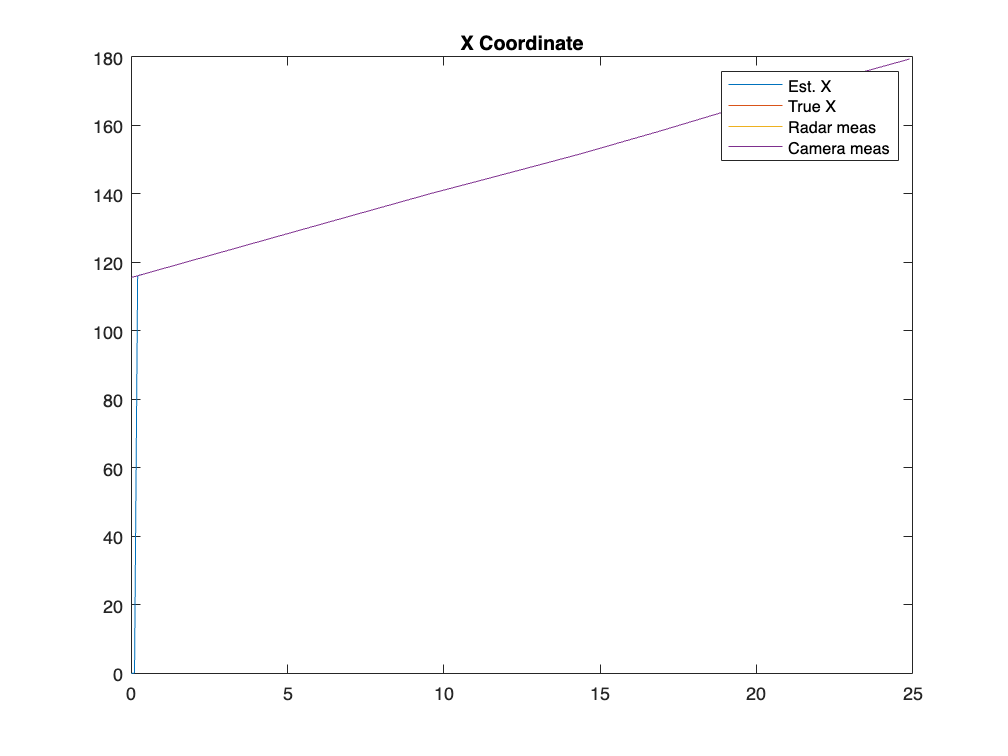

% GT_state_plot = GT_state(~isnan(radar_meas(min_index:max_index,1)),1); 
figure(1)
plot(time_vec,z_est(1,:)), hold on
plot(time_vec,GT_state(:,1)), hold on
plot(time_vec,ymeas_radar(1,:)),hold on
plot(time_vec,ymeas_camera(1,:))
title('X Coordinate')
legend('Est. X','True X','Radar meas','Camera meas')
hold off

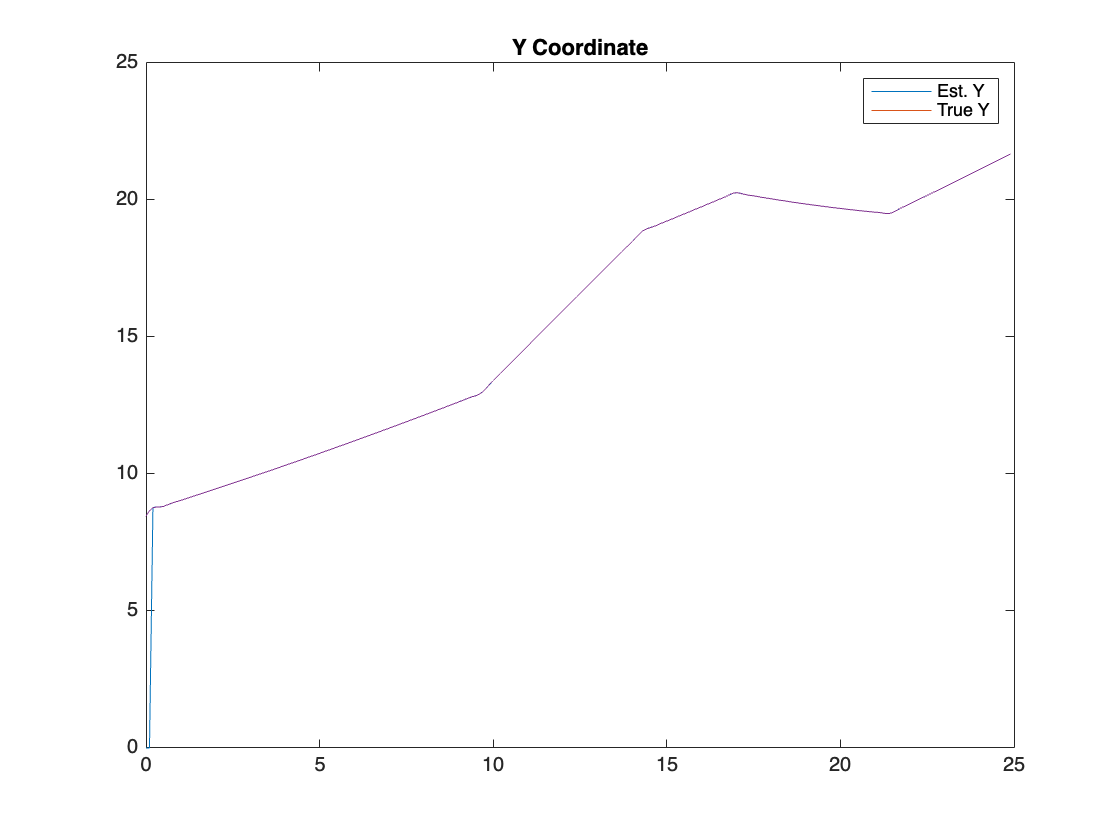

figure(2)
plot(time_vec,z_est(2,:)), hold on
plot(time_vec,GT_state(:,2)), hold on
plot(time_vec,ymeas_radar(2,:))
plot(time_vec,ymeas_camera(2,:))
title('Y Coordinate')
legend('Est. Y','True Y')
hold off

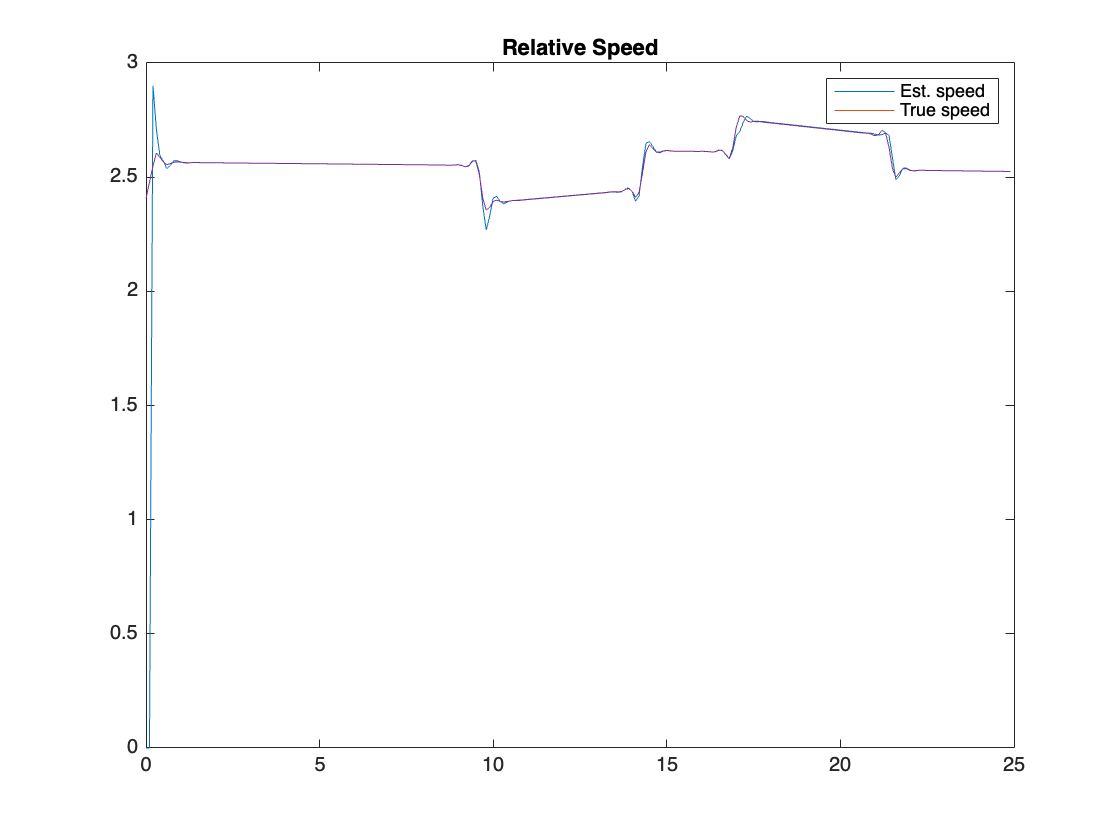

figure(3)
plot(time_vec,z_est(3,:)), hold on
plot(time_vec,GT_state(:,3)), hold on
plot(time_vec,ymeas_radar(3,:)),hold on
plot(time_vec,ymeas_camera(3,:))
title('Relative Speed')
legend('Est. speed','True speed')
hold off

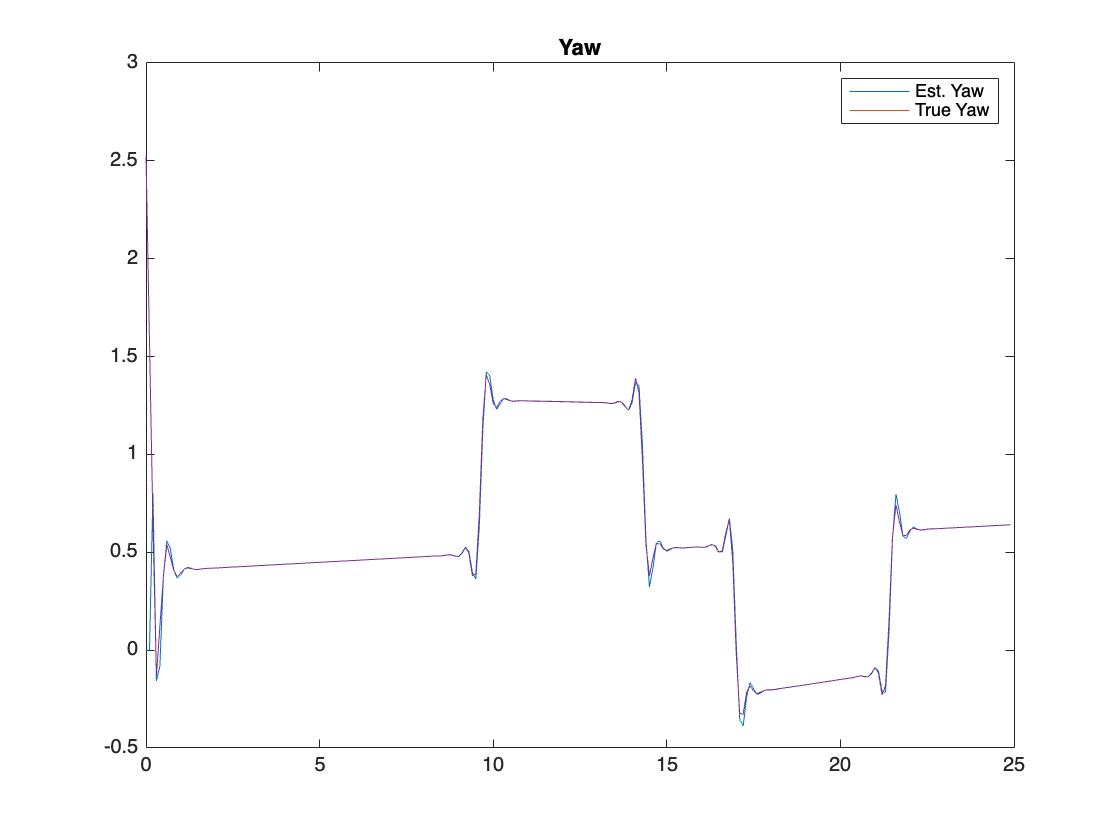


%GT_state_yaw = GT_state(min_index:max_index,4);
figure(4)
plot(time_vec,z_est(4,:)), hold on
plot(time_vec,GT_state(:,4))
if Cartesian
    plot(time_vec,ymeas_radar(4,:)),hold on
    plot(time_vec,ymeas_camera(4,:))
end
title('Yaw')
legend('Est. Yaw','True Yaw')
hold off

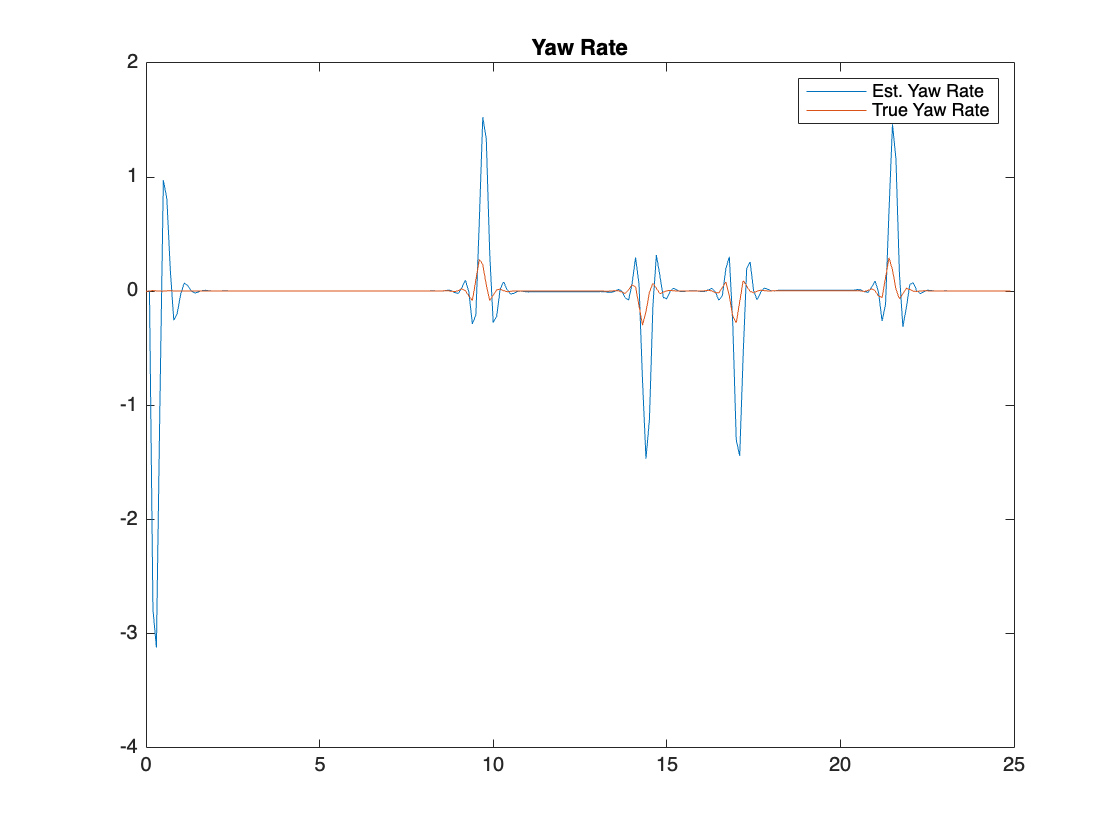

figure(5)
plot(time_vec,z_est(5,:)), hold on
plot(time_vec,GT_state(:,5))
title('Yaw Rate')
legend('Est. Yaw Rate','True Yaw Rate')
hold off

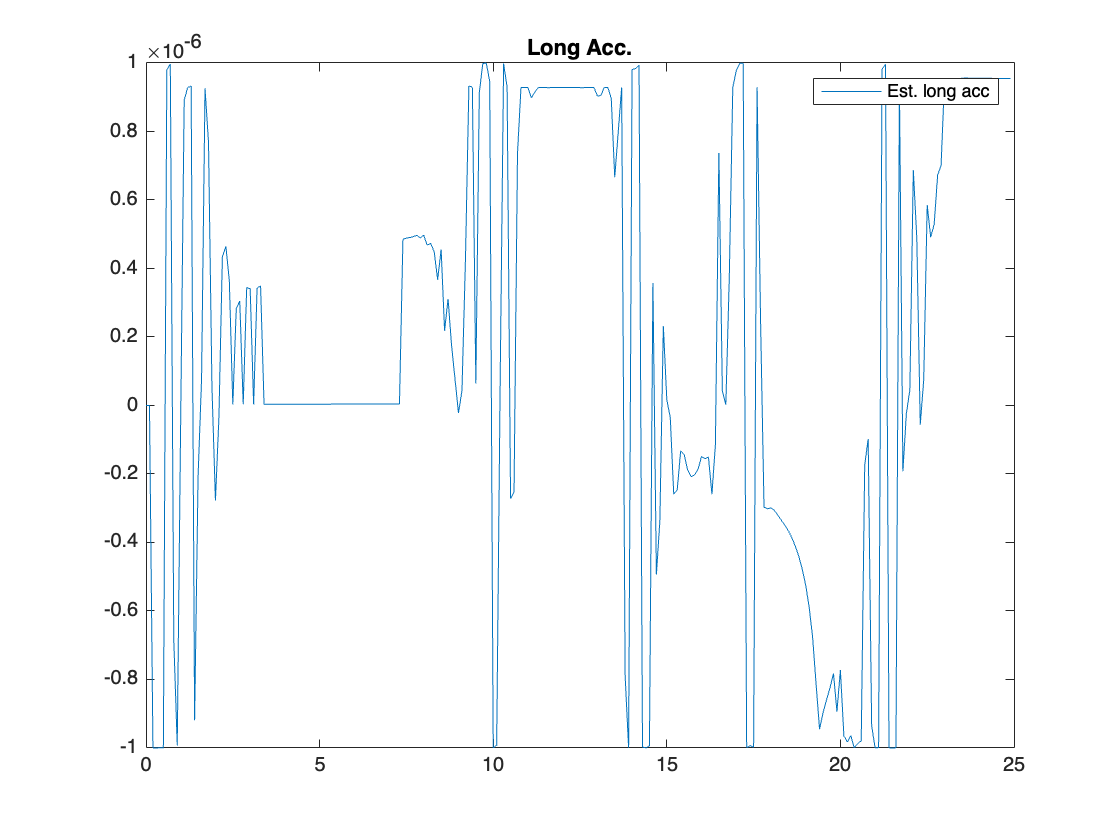

figure(6)
plot(time_vec,d_est(1,:)), hold on
%plot(GT_state(~isnan(radar_meas(min_index:max_index,1)),5))
title('Long Acc.')
legend('Est. long acc')%,'True Yaw Rate')
hold off

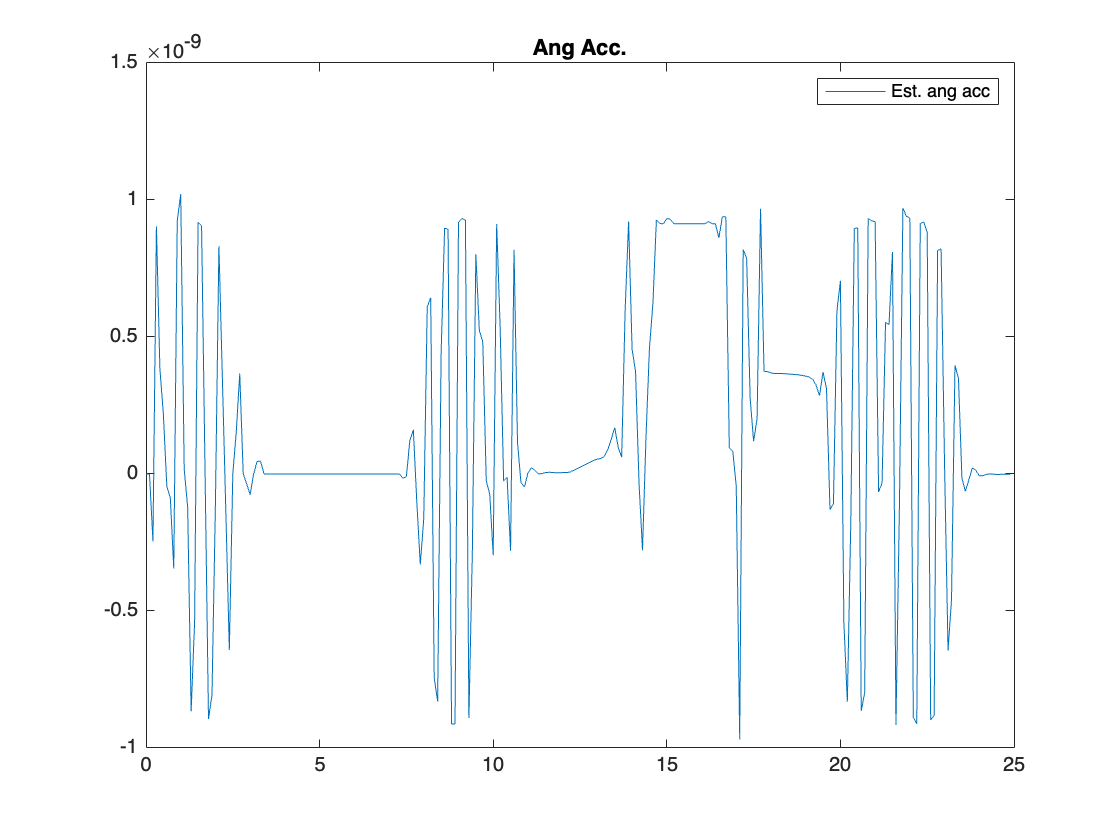

figure(7)
plot(time_vec,d_est(2,:)), hold on
% plot(GT_state(~isnan(radar_meas(min_index:max_index,1)),5))
title('Ang Acc.')
legend('Est. ang acc')%,'True Yaw Rate')
hold off